%% 初始化环境
clear; clc; close all;
rng(42); % 设置随机种子保证可重复性

%% 数据准备
% 从附件1加载收集点数据
collect_points = [0, 0, 0; % 处理厂
    12, 8, 1.2; 5, 15, 2.3; 20, 30, 1.8; 25, 10, 3.1; 35, 22, 2.7;
    18, 5, 1.5; 30, 35, 2.9; 10, 25, 1.1; 22, 18, 2.4; 38, 15, 3;
    5, 8, 1.7; 15, 32, 2.1; 28, 5, 3.2; 30, 12, 2.6; 10, 10, 1.9;
    20, 20, 2.5; 35, 30, 3.3; 8, 22, 1.3; 25, 25, 2.8; 32, 8, 3.4;
    15, 5, 1.6; 28, 20, 2.2; 38, 25, 3.5; 10, 30, 1.4; 20, 10, 2;
    30, 18, 3.6; 5, 25, 1; 18, 30, 2.3; 35, 10, 3.7; 22, 35, 1.9];

% 从附件3加载垃圾分类数据
waste_data = [0.72, 0.12, 0.06, 0.30; 1.38, 0.23, 0.05, 0.64; 1.08, 0.18, 0.04, 0.50;
    1.55, 0.31, 0.06, 1.18; 1.62, 0.27, 0.05, 0.76; 0.90, 0.20, 0.05, 0.35;
    0.77, 0.17, 0.04, 0.42; 0.66, 0.15, 0.03, 0.26; 1.32, 0.18, 0.04, 0.66;
    1.45, 0.30, 0.08, 0.68; 1.35, 0.27, 0.11, 0.97; 1.87, 0.51, 0.07, 0.95;
    2.58, 0.52, 0.13, 1.08; 1.13, 0.21, 0.06, 0.69; 0.78, 0.13, 0.07, 0.33;
    0.77, 0.19, 0.08, 0.56; 0.72, 0.27, 0.09, 0.72; 1.60, 0.35, 0.09, 0.87;
    1.50, 0.36, 0.09, 1.05; 1.08, 0.18, 0.09, 0.45; 0.91, 0.19, 0.04, 0.76;
    0.90, 0.20, 0.08, 0.33; 0.99, 0.27, 0.07, 0.47; 1.44, 0.24, 0.05, 0.67;
    1.74, 0.32, 0.12, 0.73; 1.17, 0.39, 0.13, 0.91; 1.70, 0.34, 0.17, 1.19;
    2.64, 0.66, 0.04, 1.06; 0.86, 0.22, 0.07, 0.65; 0.99, 0.20, 0.09, 0.43];

% 从附件4加载中转站数据
transfer_stations = [15, 15, 50, 6, 18, 20, 15, 5, 30;
    25, 25, 60, 8, 16, 25, 20, 6, 35;
    35, 15, 45, 10, 14, 18, 12, 4, 25;
    10, 25, 55, 7, 17, 22, 18, 5, 32;
    20, 30, 58, 9, 15, 24, 22, 7, 38];

% 从附件2加载车辆参数
vehicle_params = [8, 20, 2.5, 0.8, 0.3;  % 厨余垃圾车辆
    6, 25, 2.0, 0.6, 0.2;  % 可回收物车辆
    3, 10, 5.0, 1.2, 0.5;  % 有害垃圾车辆
    10, 18, 1.8, 0.7, 0.25]; % 其他垃圾车辆

% 参数设置
num_collect_points = 30;
num_transfer_stations = 5;
num_waste_types = 4;
vehicle_speed = 40; % km/h
working_hours = 12; % 6:00-18:00
annual_factor = 1/10; % 中转站建设成本年化因子

%% 第一阶段：中转站选址与分配
% 计算距离矩阵（对称路网）
all_points = [collect_points(:,1:2); transfer_stations(:,1:2)];
distance_matrix = pdist2(all_points, all_points);

% 手动设置非对称距离（根据附件5）
% 收集点4到中转站31
distance_matrix(4, 31) = 18; distance_matrix(31, 4) = 15;
% 收集点27到28
distance_matrix(27, 28) = 14; distance_matrix(28, 27) = 18;
% 收集点23到处理厂
distance_matrix(23, 1) = 45; distance_matrix(1, 23) = 40;
% 收集点9到16
distance_matrix(9, 16) = 8; distance_matrix(16, 9) = 10;

% 构建混合整数规划模型
f = [transfer_stations(:,3) * annual_factor; % 中转站建设成本（年化）
    reshape(distance_matrix(2:31, 32:36), num_collect_points * num_transfer_stations, 1)]; % 运输成本

% 约束条件
Aeq = zeros(num_collect_points, length(f));
for i = 1:num_collect_points
    Aeq(i, num_transfer_stations + (i-1)*num_transfer_stations + 1 : num_transfer_stations + i*num_transfer_stations) = 1;
end
beq = ones(num_collect_points, 1);

% 容量约束
A = zeros(num_waste_types * num_transfer_stations, length(f));
for j = 1:num_transfer_stations
    for k = 1:num_waste_types
        row = (j-1)*num_waste_types + k;
        A(row, j) = -transfer_stations(j, 5+k); % 容量限制
        for i = 1:num_collect_points
            A(row, num_transfer_stations + (i-1)*num_transfer_stations + j) = waste_data(i, k);
        end
    end
end
b = zeros(num_waste_types * num_transfer_stations, 1);

% 变量边界
lb = zeros(length(f), 1);
ub = ones(length(f), 1);
ub(1:num_transfer_stations) = 1; % 中转站是否选址
ub(num_transfer_stations+1:end) = 1; % 分配变量

% 求解
options = optimoptions('intlinprog', 'Display', 'off');
[x, fval, exitflag] = intlinprog(f, 1:length(f), A, b, Aeq, beq, lb, ub, options);

% 提取结果
selected_stations = x(1:num_transfer_stations) > 0.5;
station_allocation = reshape(x(num_transfer_stations+1:end), num_transfer_stations, num_collect_points)';
[~, assigned_station] = max(station_allocation, [], 2);
assigned_station = assigned_station + num_collect_points; % 转换为全局编号

disp('第一阶段结果：');

第一阶段结果：


disp(['选中的中转站编号: ', num2str(find(selected_stations)')]);

选中的中转站编号: 1  2  3  4  5


disp('收集点分配结果:');

收集点分配结果:


disp([(1:num_collect_points)', assigned_station]);

     1    31
     2    34
     3    35
     4    31
     5    35
     6    32
     7    33
     8    34
     9    32
    10    34
    11    32
    12    31
    13    35
    14    35
    15    34
    16    35
    17    32
    18    34
    19    32
    20    33
    21    32
    22    33
    23    34
    24    32
    25    33
    26    32
    27    32
    28    34
    29    34
    30    33




%% 第二阶段：路径优化
% 为每个中转站和每种垃圾类型规划路径
vehicle_routes = cell(num_transfer_stations, num_waste_types);
total_cost = 0;
total_emission = 0;

for j = 1:num_transfer_stations
    if ~selected_stations(j), continue; end
    
    % 获取分配给该中转站的收集点
    points_in_station = find(assigned_station == j + num_collect_points);
    if isempty(points_in_station), continue; end
    
    for k = 1:num_waste_types
        % 获取该类型垃圾量
        waste_volumes = waste_data(points_in_station, k);
        valid_points = points_in_station(waste_volumes > 0);
        waste_volumes = waste_volumes(waste_volumes > 0);
        
        if isempty(valid_points), continue; end
        
        % 车辆参数
        capacity = vehicle_params(k, 1);
        volume = vehicle_params(k, 2);
        cost_per_km = vehicle_params(k, 3);
        alpha = vehicle_params(k, 4);
        beta = vehicle_params(k, 5);
        
        % 使用节约算法求解CVRP
        [routes, cost, emission] = solveCVRP(valid_points, waste_volumes, ...
            j + num_collect_points, capacity, volume, distance_matrix, ...
            cost_per_km, alpha, beta);
        
        vehicle_routes{j, k} = routes;
        total_cost = total_cost + cost;
        total_emission = total_emission + emission;
    end
end

disp('第二阶段结果：');

第二阶段结果：


disp(['总运输成本: ', num2str(total_cost)]);

总运输成本: 4998.3737


disp(['总碳排放量: ', num2str(total_emission)]);

总碳排放量: 2983.994


disp('车辆路径详情:');

车辆路径详情:


for j = 1:num_transfer_stations
    if ~selected_stations(j), continue; end
    for k = 1:num_waste_types
        if ~isempty(vehicle_routes{j, k})
            disp(['中转站 ', num2str(j), ' 类型 ', num2str(k), ' 路径:']);
            for r = 1:length(vehicle_routes{j, k})
                disp(['  车辆 ', num2str(r), ': ', num2str(vehicle_routes{j, k}{r})]);
            end
        end
    end
end

中转站 1 类型 1 路径:


  车辆 1: 31   4   1  12  31


中转站 1 类型 2 路径:


  车辆 1: 31   4   1  12  31


中转站 1 类型 3 路径:


  车辆 1: 31   4   1  12  31


中转站 1 类型 4 路径:


  车辆 1: 31   4   1  12  31


中转站 2 类型 1 路径:


  车辆 1: 32  17   9  19  32
  车辆 2: 32  27   6  24  11  21  26  32


中转站 2 类型 2 路径:


  车辆 1: 32   9  19  17  27   6  24  11  21  26  32


中转站 2 类型 3 路径:


  车辆 1: 32   9  19  17  27   6  24  11  21  26  32


中转站 2 类型 4 路径:


  车辆 1: 32   9  19  17  27   6  24  11  21  26  32


中转站 3 类型 1 路径:


  车辆 1: 33  30   7  22  25  20  33


中转站 3 类型 2 路径:


  车辆 1: 33  30   7  22  25  20  33


中转站 3 类型 3 路径:


  车辆 1: 33  30   7  22  25  20  33


中转站 3 类型 4 路径:


  车辆 1: 33  30   7  22  25  20  33


中转站 4 类型 1 路径:


  车辆 1: 34  15   2  28  29   8  18  34
  车辆 2: 34  10  23  34


中转站 4 类型 2 路径:


  车辆 1: 34  15  23  10   2  28  29   8  18  34


中转站 4 类型 3 路径:


  车辆 1: 34  15  23  10   2  28  29   8  18  34


中转站 4 类型 4 路径:


  车辆 1: 34  15  23  10   2  28  29   8  18  34


中转站 5 类型 1 路径:


  车辆 1: 35  13   5  14  16   3  35


中转站 5 类型 2 路径:


  车辆 1: 35  13   5  14  16   3  35


中转站 5 类型 3 路径:


  车辆 1: 35  13   5  14  16   3  35


中转站 5 类型 4 路径:


  车辆 1: 35  13   5  14  16   3  35


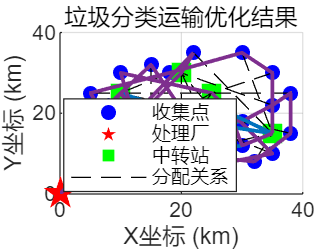


%% 可视化结果
figure;
% 绘制收集点
scatter(collect_points(2:end,1), collect_points(2:end,2), 'b', 'filled');
hold on;
% 绘制处理厂
scatter(collect_points(1,1), collect_points(1,2), 200, 'r', 'p', 'filled');
% 绘制选中的中转站
selected_idx = find(selected_stations);
scatter(transfer_stations(selected_idx,1), transfer_stations(selected_idx,2), 100, 'g', 's', 'filled');

% 绘制分配关系
for i = 1:num_collect_points
    station_idx = assigned_station(i) - num_collect_points;
    if station_idx > 0 && station_idx <= num_transfer_stations && selected_stations(station_idx)
        plot([collect_points(i+1,1), transfer_stations(station_idx,1)], ...
             [collect_points(i+1,2), transfer_stations(station_idx,2)], 'k--');
    end
end

% 绘制车辆路径
colors = lines(num_waste_types);
for j = 1:num_transfer_stations
    if ~selected_stations(j), continue; end
    for k = 1:num_waste_types
        if ~isempty(vehicle_routes{j, k})
            for r = 1:length(vehicle_routes{j, k})
                route = vehicle_routes{j, k}{r};
                x_route = all_points(route, 1);
                y_route = all_points(route, 2);
                plot(x_route, y_route, 'Color', colors(k,:), 'LineWidth', 1.5);
            end
        end
    end
end

legend('收集点', '处理厂', '中转站', '分配关系', 'Location', 'best');
title('垃圾分类运输优化结果');
xlabel('X坐标 (km)'); ylabel('Y坐标 (km)');
grid on;


%% CVRP求解函数
function [routes, total_cost, total_emission] = solveCVRP(customers, demands, depot, capacity, volume, distance_matrix, cost_per_km, alpha, beta)
    % 初始化
    n = length(customers);
    if n == 0
        routes = {};
        total_cost = 0;
        total_emission = 0;
        return;
    end
    
    % 计算节约值
    savings = zeros(n*(n-1)/2, 3);
    idx = 1;
    for i = 1:n
        for j = i+1:n
            s = distance_matrix(depot, customers(i)) + distance_matrix(depot, customers(j)) - distance_matrix(customers(i), customers(j));
            savings(idx,:) = [i, j, s];
            idx = idx + 1;
        end
    end
    savings = sortrows(savings, -3); % 按节约值降序排列
    
    % 初始化路线
    routes = cell(n, 1);
    route_demands = zeros(n, 1);
    for i = 1:n
        routes{i} = [depot, customers(i), depot];
        route_demands(i) = demands(i);
    end
    
    % 合并路线
    for s = 1:size(savings, 1)
        i = savings(s,1);
        j = savings(s,2);
        
        % 找到包含i和j的路线
        route_i = []; route_j = [];
        for r = 1:length(routes)
            if isempty(routes{r}), continue; end
            if ismember(customers(i), routes{r}(2:end-1))
                route_i = r;
            end
            if ismember(customers(j), routes{r}(2:end-1))
                route_j = r;
            end
        end
        
        % 如果i和j在不同路线且合并后不超载
        if route_i ~= route_j && ~isempty(route_i) && ~isempty(route_j) && ...
                route_demands(route_i) + route_demands(route_j) <= capacity
            
            % 合并路线
            if routes{route_i}(end-1) == customers(i) && routes{route_j}(2) == customers(j)
                % i...depot + depot.j... → i...j...
                new_route = [routes{route_i}(1:end-1), routes{route_j}(2:end)];
            elseif routes{route_i}(2) == customers(i) && routes{route_j}(end-1) == customers(j)
                % depot.i... + ...j.depot → ...j.i...
                new_route = [routes{route_j}(1:end-1), routes{route_i}(2:end)];
            else
                continue; % 无法合并
            end
            
            % 更新路线
            routes{route_i} = new_route;
            route_demands(route_i) = route_demands(route_i) + route_demands(route_j);
            routes{route_j} = [];
            route_demands(route_j) = 0;
        end
    end
    
    % 移除空路线
    routes = routes(~cellfun(@isempty, routes));
    
    % 计算总成本和碳排放
    total_cost = 0;
    total_emission = 0;
    for r = 1:length(routes)
        route = routes{r};
        route_dist = 0;
        route_load = 0;
        for n = 1:length(route)-1
            route_dist = route_dist + distance_matrix(route(n), route(n+1));
            if route(n) ~= depot
                route_load = route_load + demands(customers == route(n));
            end
        end
        total_cost = total_cost + route_dist * cost_per_km;
        total_emission = total_emission + alpha * route_dist + beta * route_dist * route_load;
    end
end